# Ex 1 - Consensus [part 1]

clear variables
close all
clc

## Rng seed

rng(1)

## Graph initialization

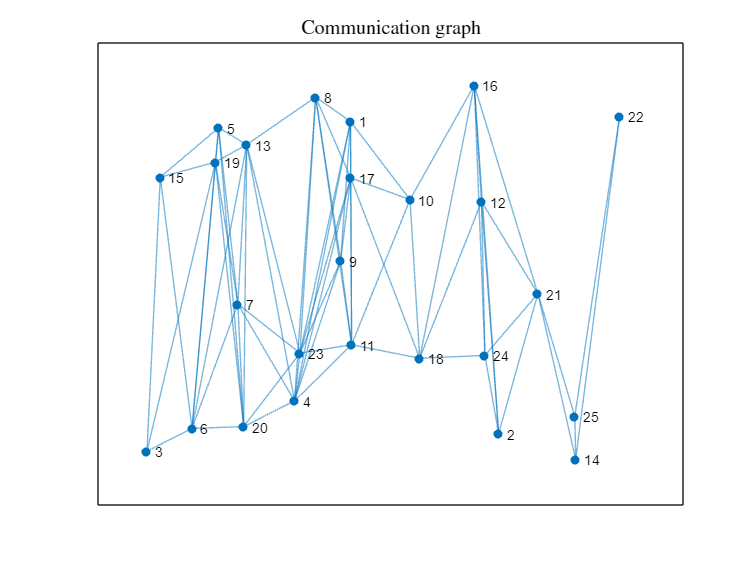

N = 25;                         % number of nodes
r = 0.2;                        % radius of random graph

[A,L] = random_graph(N,r,true); % generate random graph

d = sum(A,1);                   % nodes' degrees

v = rand(N,1);                  % observations
v_avg = mean(v);                % value of average consensus

sim_len = 200;                  % simulations length

## Ratio consensus

#### Initialize nodes' auxiliary variables

Initialization of the auxiliary variables stored in the nodes. The initial values of Y and S are modified with respect to the original to see what happens to the consensus algorithm.

% modification factors
y_factor = 1;
y_offset = 0;
s_factor = 1.5;
s_offset = 0;

% initialize (modified) auxiliary variables
Y = v*y_factor + y_offset;
S = ones(N,1)*s_factor + s_offset;

% modifiy individual values of Y and S
% S(3) = S(3)*3;
% S(12) = S(12)*0.1;
% Y(2) = Y(2)*1.5;

#### Initialize nodes' state

X = [v, zeros(N,sim_len)];      % trajectories of nodes states

#### Generate consensus matrix

P = zeros(N);               

for i = 1:N
    for j = find(A(i,:))
        P(i,j) = 1/(1+d(j));    % off-diagonal elements
    end
    P(i,i) = 1/(1+d(i));        % diagonal elements
end


#### Compute consensus

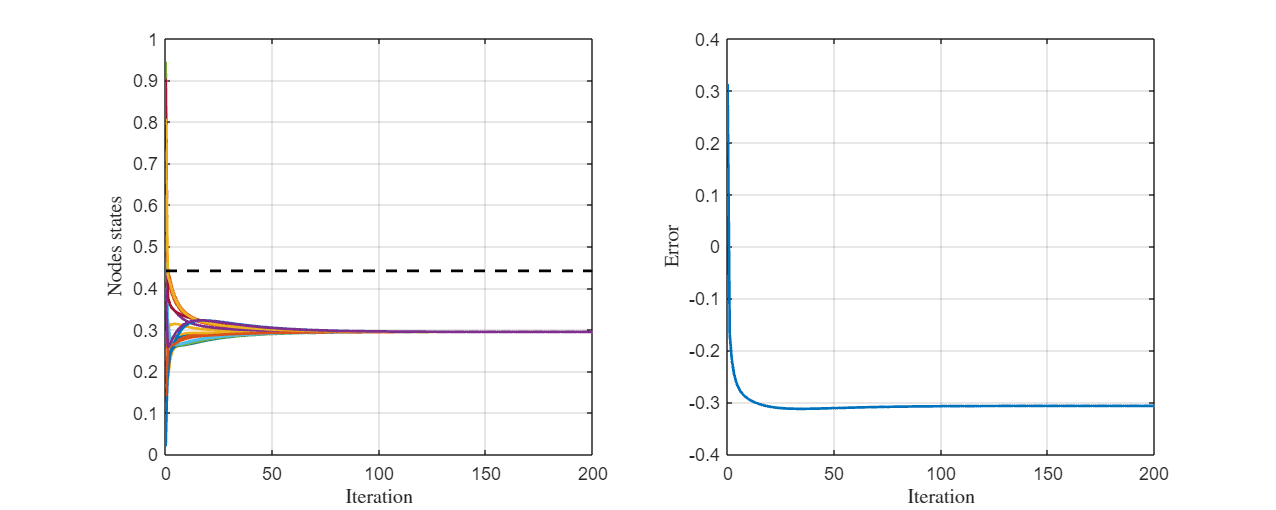

for k = 1:sim_len
    
    % update auxiliary variables
    Y = P*Y;
    S = P*S;
    
    % update nodes' states
    X(:,k+1) = Y./S;
    
end

% plot result
plot_results(X,v_avg)

## Asymmetric broadcast consensus

### Original broadcast consensus

Only one node is activate at each time step and sends its state to all the neighbours, which incorporate it depending on the mixing parameter.

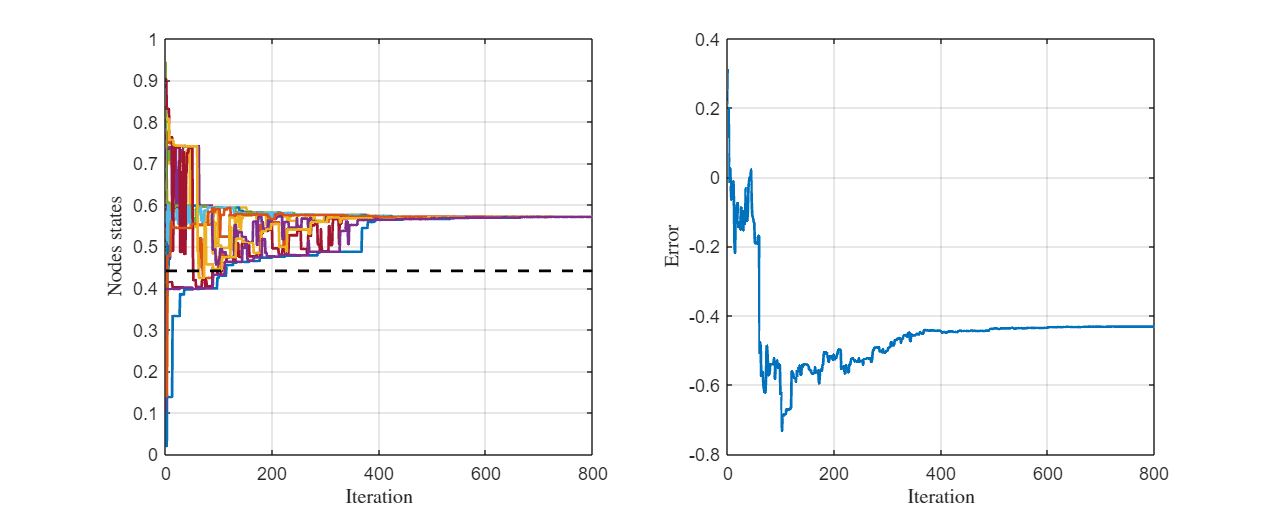

q = 0.25; % mixing parameter

X = [v, zeros(N,4*sim_len)];    % trajectories of nodes states

for k = 1:4*sim_len
    
    X(:,k+1) = X(:,k);          % propagate old states
    
    i = randi(N);               % choose broadcaster node
    
    % update neighbors' states
    for j = find(A(i,:))
        
        X(j,k+1) = (1-q)*X(i,k) + q*X(j,k);
    
    end
end

% plot result
plot_results(X,v_avg)

### Modified broadcast consensus

Two nodes are awakened at each step (in synch, not sequentially) and transmit their data to their neighbours.

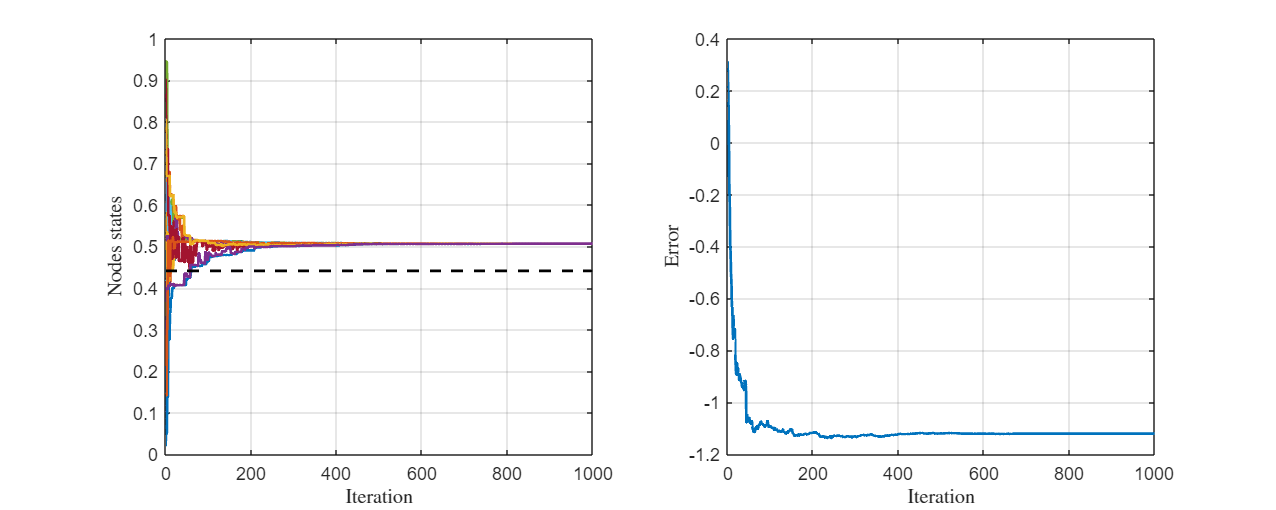

q = 0.5; % mixing parameter
n_activated_nodes = 2;
sim_len = 1000;

X = [v, zeros(N,sim_len)];    % trajectories of nodes states

for k = 1:sim_len
    
    X(:,k+1) = X(:,k);          % propagate old states
    

    i1 = randi(N);              % choose first broadcaster node
    i2 = randi(N);              % choose second broadcaster node
    
    % update neighbors' states
    J1 = find(A(i1,:));
    J2 = find(A(i2, :));
    for j1 = J1
        if ismember(j1, J2)
            X(j1, k+1) = 0.5*(1-q)*X(i1, k) + 0.5*(1-q)*X(i2,k) + q*X(j1, k);
        else
            X(j1, k+1) = (1-q)*X(i1, k) + q*X(j1, k);
        end
    end
    for j2 = J2
        if ismember(j2, J1)
            continue    % the node was already updated in the previous routine
        else
            X(j2, k+1) = (1-q)*X(i2, k) + q*X(j2, k);
        end
    end
end

% plot result
plot_results(X,v_avg)

## Noisy average consensus

sim_len = 2000;                 % simulations length
variance = 0.001;               % gaussian white noise variance

#### Generate consensus matrix

eps = 1/max(diag(L));           % choose epsilon
P = eye(N) - eps*L;             % design consensus matrix

X = [v, zeros(N,sim_len)];      % trajectories of nodes states

### Add noise and compute consensus

#### 1) Multiplicative noise

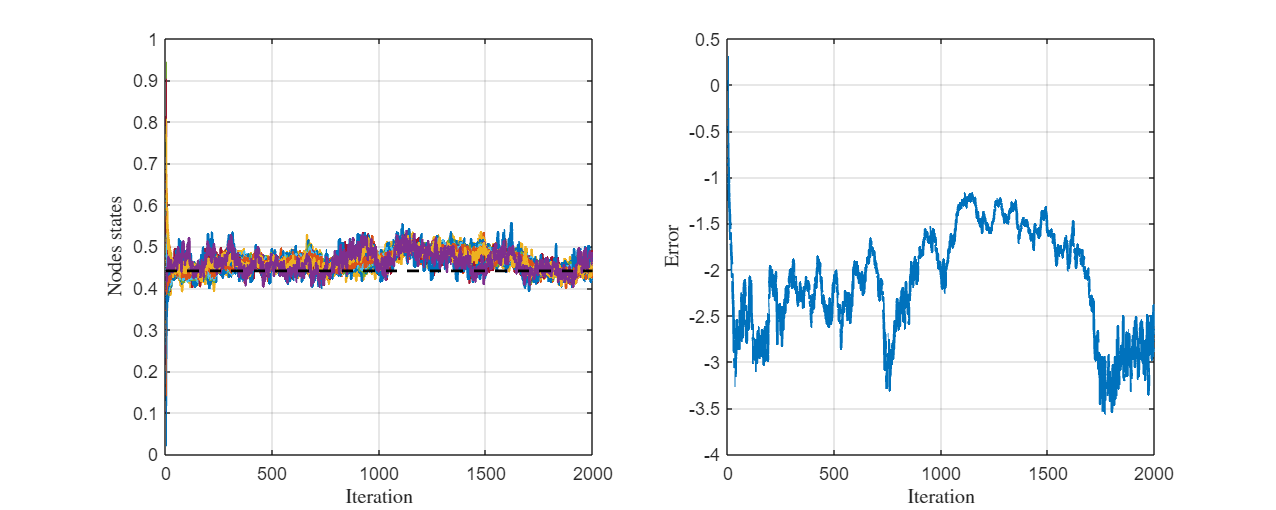

for k = 1:sim_len

    P_noisy = P.*(1+sqrt(variance)*randn(N));   % multiplicative noise
    X(:,k+1) = P_noisy*X(:,k);                  % update nodes' states
    
end

% plot result
plot_results(X,v_avg)

#### 2) Additive noise

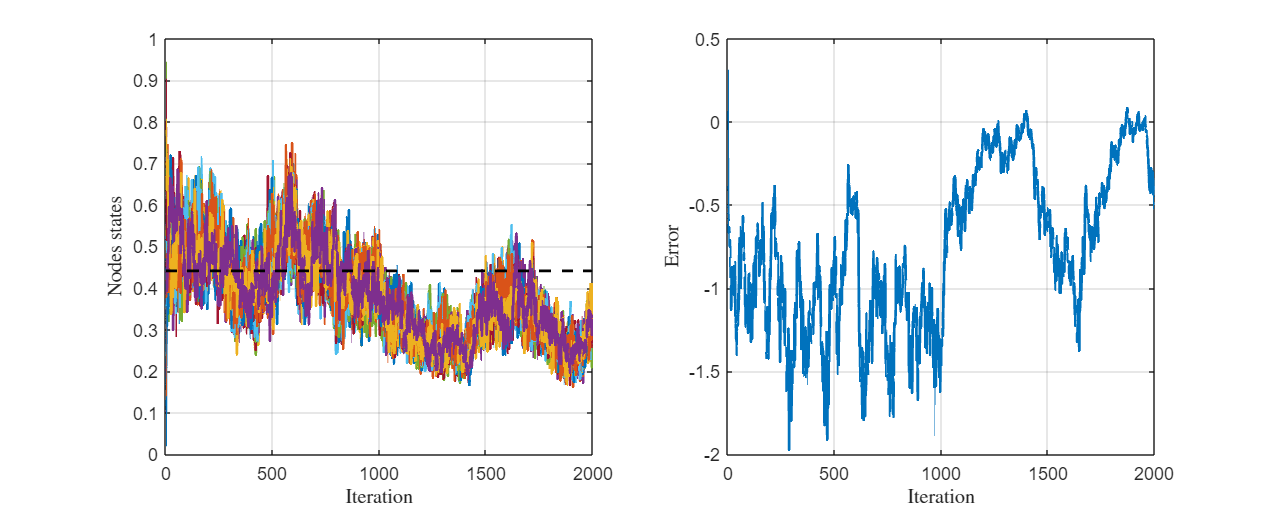

for k = 1:sim_len

    P_noisy = P + ceil(P).*(sqrt(variance)*randn(N));     % additive noise (only on active connections)
    X(:,k+1) = P_noisy*X(:,k);                          % update nodes' states
    
end

% plot result
plot_results(X,v_avg)